Load data

data = preprocess('data/china.csv');

Rsiduals visualization      

[tr,y_tr,te,y_te] = train_test_split(data);
model_all = ols(tr,y_tr);

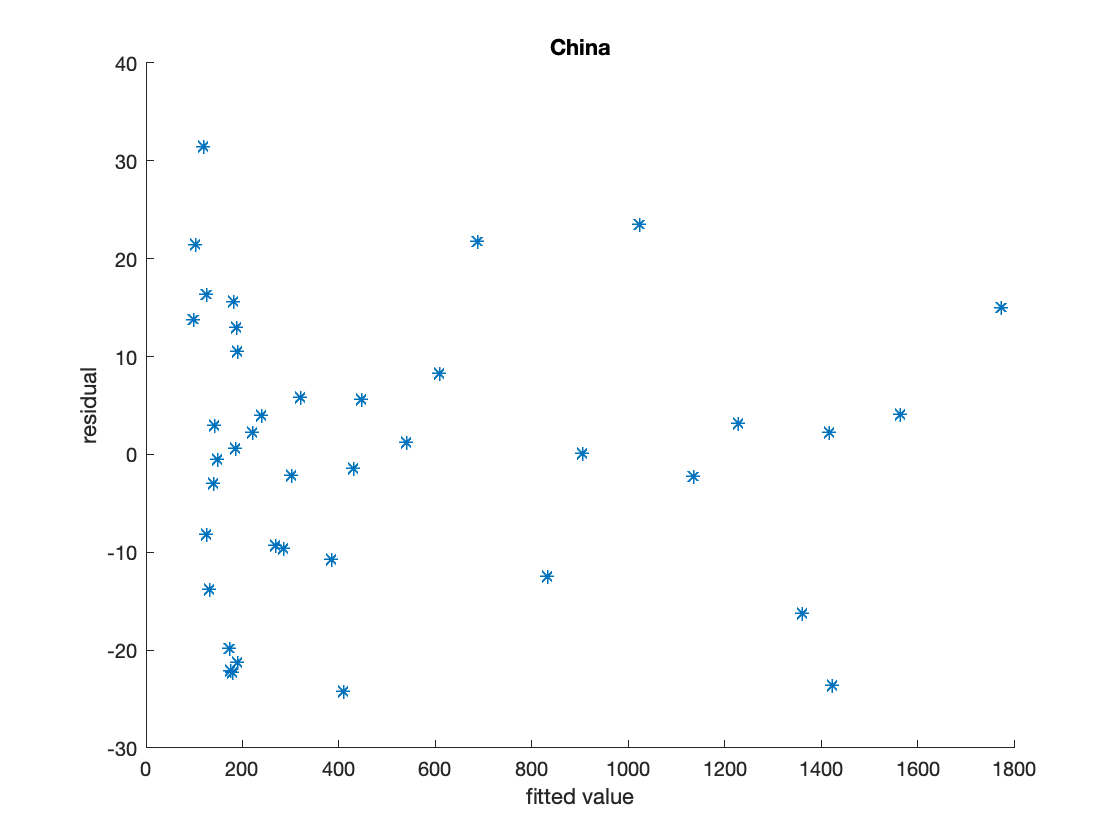

x = 1:1:size(tr);
scatter(model_all.pred,model_all.residuals,'*');
ylabel('residual') ;
xlabel('fitted value') ;
title('China');

% normalise and select subfeatures
select = [true,false,true,false,true,false,true,true,true,true,false,true,false,false,true,false,false,false];
[tr,te]  = standardize(tr(:,select),te(:,select));
model    = ols(tr,y_tr);
te_stats = test_model(model.beta,te,y_te);

Breusch Pagan Test

[BP_stat,BP_crit,H] = Breusch_Pagan_test(tr,model.residuals,0.95);
% with matrix input

FSL

model_FGLS = FGLS(tr,y_tr);
% Breush Pagan on FGLS
[BP_stat_FGLS,BP_crit_FGLS,H_FGLS] = Breusch_Pagan_test(tr,model_FGLS.residuals,0.95);


ee

beta = fgls(tr(:,2:end),y_tr);
res = y_tr-  (tr*beta);
[BP_stat_FGLS_2,BP_crit_FGLS_2,H_FGLS_2] = Breusch_Pagan_test(tr,res,0.95);
te_stats_FGLS = test_model(beta,te,y_te);